syms u(t) v(t)
de1 = diff(u) == 3*u + 4*v;
ode2 = diff(v) == -4*u + 3*v;
odes = [de1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}u\left(t\right)=3\,u\left(t\right)+4\,v\left(t\right)\\ \frac{\partial }{\partial t}v\left(t\right)=3\,v\left(t\right)-4\,u\left(t\right) \end{array}\right)$$

S = dsolve(odes)

S = struct with fields:
    v: [1×1 sym]
    u: [1×1 sym]


uSol(t) = S.u

$$uSol(t) = C_{2}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}+C_{1}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

vSol(t) = S.v

$$vSol(t) = C_{1}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}-C_{2}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

[uSol(t),vSol(t)] = dsolve(odes)

$$uSol(t) = C_{2}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}+C_{1}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

$$vSol(t) = C_{1}\,\cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}-C_{2}\,\sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

cond1 = u(0) == 0;
cond2 = v(0) == 1;
conds = [cond1; cond2];
[uSol(t),vSol(t)] = dsolve(odes,conds)

$$uSol(t) = \sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

$$vSol(t) = \cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

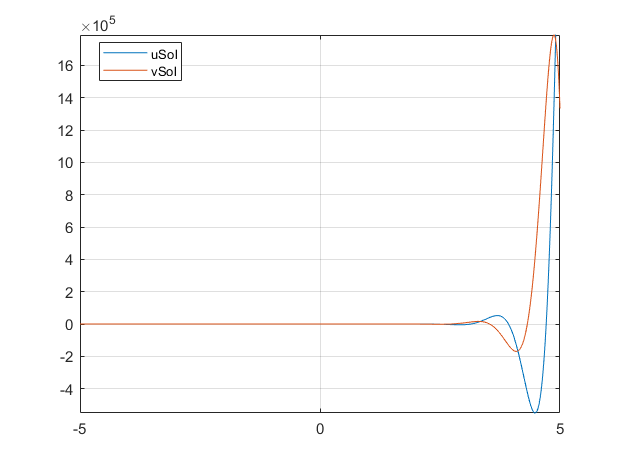

fplot(uSol)
hold on
fplot(vSol)
grid on
legend('uSol','vSol','Location','best')